# Parameter distributions and clustering

## IKtof

### Parameter density estimation

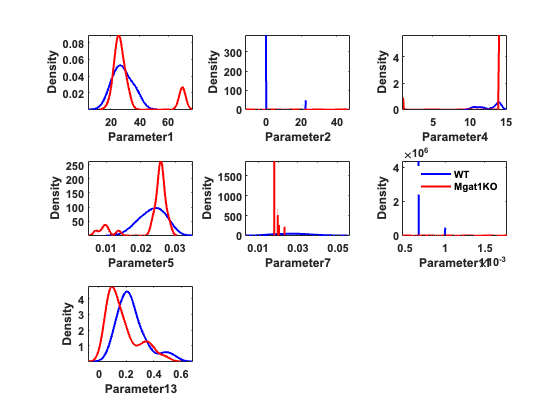

pktof = readtable("exp42_pktof.csv");
pidx = unique(pktof.param);

figure
for i=1:length(pidx)
    psub = pktof(pktof.param==pidx(i),:);
    psub_wt = psub(string(psub.Group)=="WT",:);
    psub_ko = psub(string(psub.Group)=="Mgat1KO",:);

    [f1,xi1] = ksdensity(psub_wt.value);
    [f2,xi2] = ksdensity(psub_ko.value);
    
    subplot(3,3,i)
    plot(xi1,f1, 'Color','blue', 'LineWidth',2)
    hold on
    plot(xi2,f2, 'Color','red', 'LineWidth',2)
    hold off
    axis tight
    xlabel(strcat('Parameter', num2str(pidx(i))))
    ylabel('Density')
    set(gca, 'FontName','Arial', 'FontSize',11, 'FontWeight','bold')

    if i==6
        legend(["WT","Mgat1KO"])
        legend box off
    end
end

### Clustering - PCA

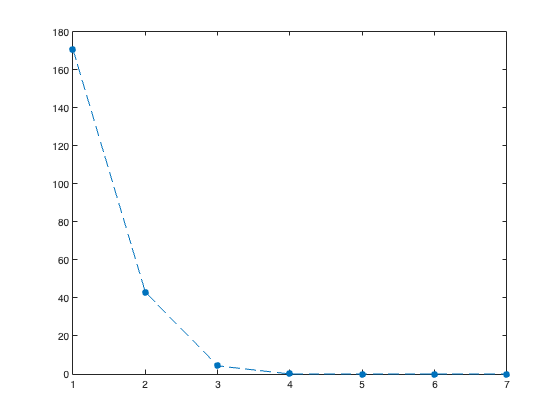

% data modification
nrow = size(pktof,1)/length(pidx);
pktof2 = array2table(NaN(nrow,length(pidx)+1));
pktof2.Properties.VariableNames(1) = {'Group'};
pktof2.Group = pktof(pktof.param==pidx(1),:).Group;

for i=1:length(pidx)
    pktof2.Properties.VariableNames(i+1) = {strcat('P',num2str(pidx(i)))};
    pktof2(:,i+1)= pktof(pktof.param==pidx(i),'value');
end

[~,score,latent] = pca(table2array(pktof2(:,2:end)));

figure
plot(latent,'--.', 'MarkerSize',20)

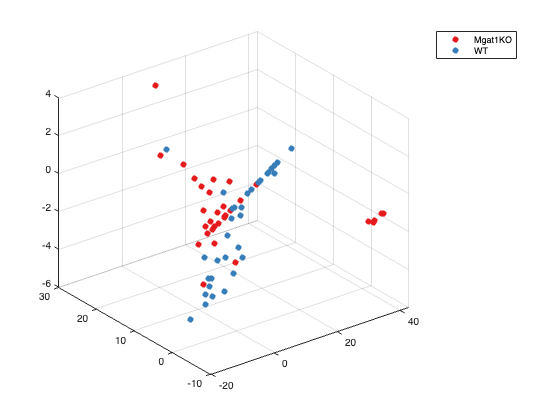

g = NaN(nrow,1);
g(pktof2.Group == "Mgat1KO") = 1;
g(pktof2.Group == "WT") = 2;
c = brewermap(length(unique(g)),'Set1');

scatter3(score(g==1,1),score(g==1,2),score(g==1,3), 'filled', 'CData',c(g(g==1),:))
hold on
scatter3(score(g==2,1),score(g==2,2),score(g==2,3), 'filled', 'CData',c(g(g==2),:))
hold off
legend(["Mgat1KO","WT"])

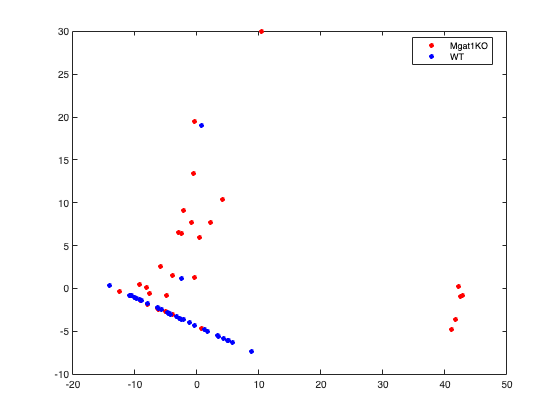

g2 = categorical(pktof2.Group);
gscatter(score(:,1),score(:,2),g2, 'rb');

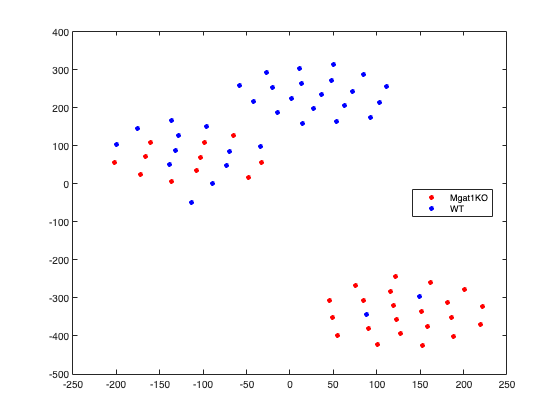

embd = tsne(table2array(pktof2(:,2:end)),'Algorithm','exact','Distance','spearman');
gscatter(embd(:,1),embd(:,2),g2,'rb')

## IKslow1

### Parameter density estimation

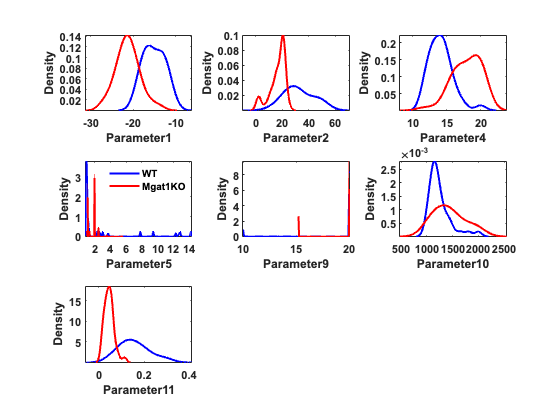

pkslow1 = readtable("exp42_pkslow1.csv");
pidx = unique(pkslow1.param);

figure
for i=1:length(pidx)
    psub = pkslow1(pkslow1.param==pidx(i),:);
    psub_wt = psub(string(psub.Group)=="WT",:);
    psub_ko = psub(string(psub.Group)=="Mgat1KO",:);

    [f1,xi1] = ksdensity(psub_wt.value);
    [f2,xi2] = ksdensity(psub_ko.value);
    
    subplot(3,3,i)
    plot(xi1,f1, 'Color','blue', 'LineWidth',2)
    hold on
    plot(xi2,f2, 'Color','red', 'LineWidth',2)
    hold off
    axis tight
    xlabel(strcat('Parameter', num2str(pidx(i))))
    ylabel('Density')
    set(gca, 'FontName','Arial', 'FontSize',11, 'FontWeight','bold')
    
    if i==4
        legend('WT','Mgat1KO', 'Location','best')
        legend box off
    end
end

### Clustering - PCA

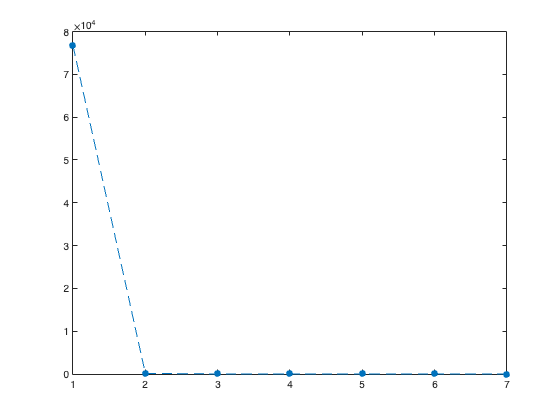

pkslow12 = array2table(NaN(nrow,length(pidx)+1));
pkslow12.Properties.VariableNames(1) = {'Group'};
pkslow12.Group = pkslow1(pkslow1.param==pidx(1),:).Group;

for i=1:length(pidx)
    pkslow12.Properties.VariableNames(i+1) = {strcat('P',num2str(pidx(i)))};
    pkslow12(:,i+1)= pkslow1(pkslow1.param==pidx(i),'value');
end

[~,score,latent] = pca(table2array(pkslow12(:,2:end)));

figure
plot(latent,'--.','MarkerSize',20)

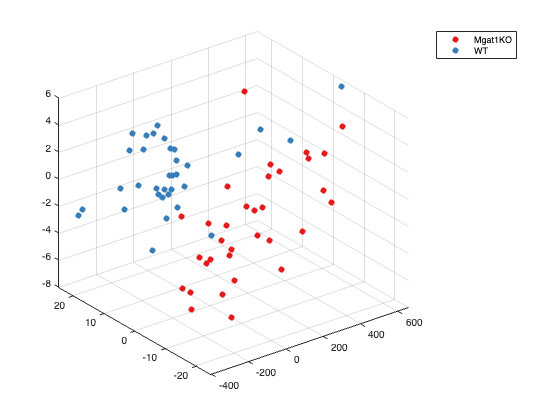

scatter3(score(g==1,1),score(g==1,2),score(g==1,3), 'filled', 'CData',c(g(g==1),:))
hold on
scatter3(score(g==2,1),score(g==2,2),score(g==2,3), 'filled', 'CData',c(g(g==2),:))
hold off
legend(["Mgat1KO","WT"])

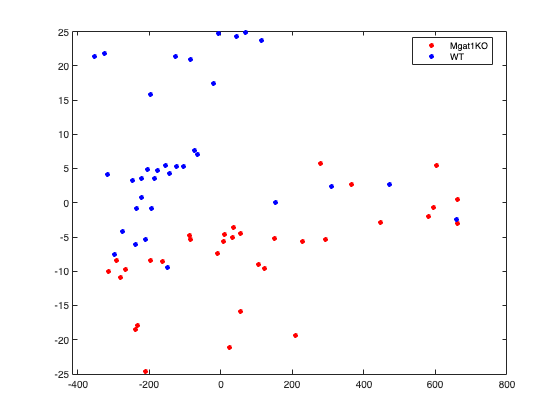

gscatter(score(:,1),score(:,2),g2,'rb')

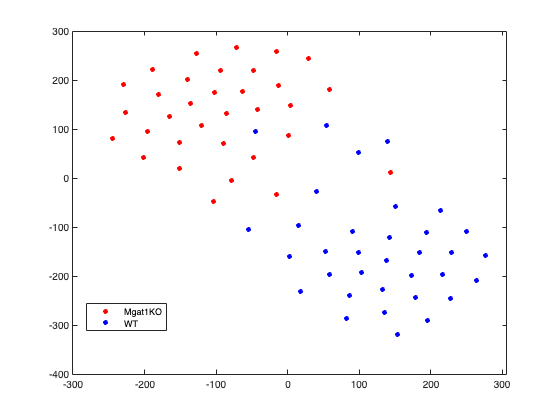

embd = tsne(normalize(table2array(pkslow12(:,2:end))),'Algorithm','exact','Distance','spearman');
gscatter(embd(:,1),embd(:,2),g2,'rb')

## IKss

### Parameter density estimation

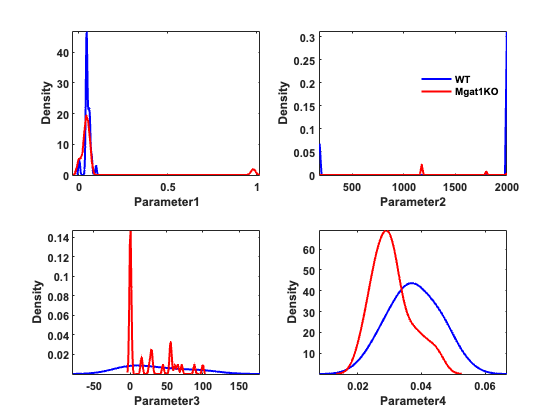

pkss = readtable("exp42_pkss.csv");
pidx = unique(pkss.param);

figure
for i=1:length(pidx)
    psub = pkss(pkss.param==pidx(i),:);
    psub_wt = psub(string(psub.Group)=="WT",:);
    psub_ko = psub(string(psub.Group)=="Mgat1KO",:);

    [f1,xi1] = ksdensity(psub_wt.value);
    [f2,xi2] = ksdensity(psub_ko.value);
    
    subplot(2,2,i)
    plot(xi1,f1, 'Color','blue', 'LineWidth',2)
    hold on
    plot(xi2,f2, 'Color','red', 'LineWidth',2)
    hold off
    axis tight
    xlabel(strcat('Parameter', num2str(pidx(i))))
    ylabel('Density')
    set(gca, 'FontName','Arial', 'FontSize',11, 'FontWeight','bold')

    if i==2
        legend('WT','Mgat1KO', 'Location','best')
        legend box off
    end
end

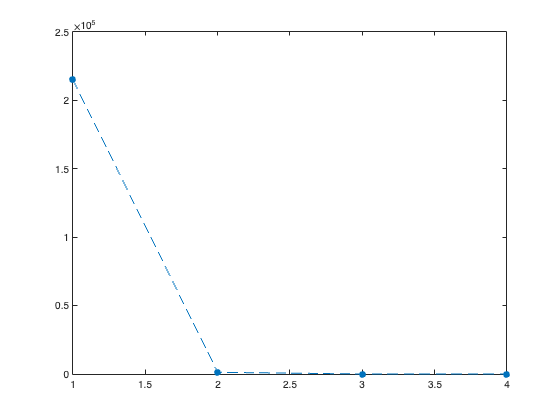

pkss2 = array2table(NaN(nrow,length(pidx)+1));
pkss2.Properties.VariableNames(1) = {'Group'};
pkss2.Group = pkss(pkss.param==pidx(1),:).Group;

for i=1:length(pidx)
    pkss2.Properties.VariableNames(i+1) = {strcat('P',num2str(pidx(i)))};
    pkss2(:,i+1)= pkss(pkss.param==pidx(i),'value');
end

[~,score,latent] = pca(table2array(pkss2(:,2:end)));

figure
plot(latent,'--.','MarkerSize',20)

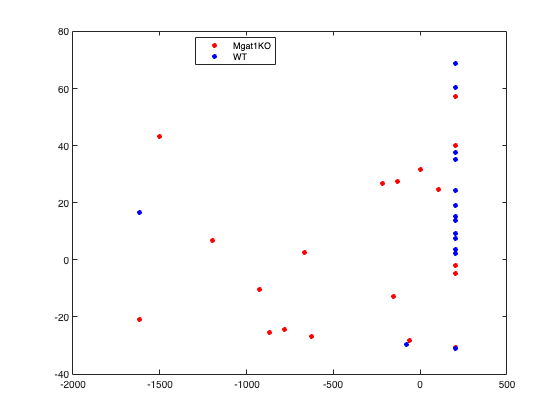

gscatter(score(:,1),score(:,2),g2,'rb')

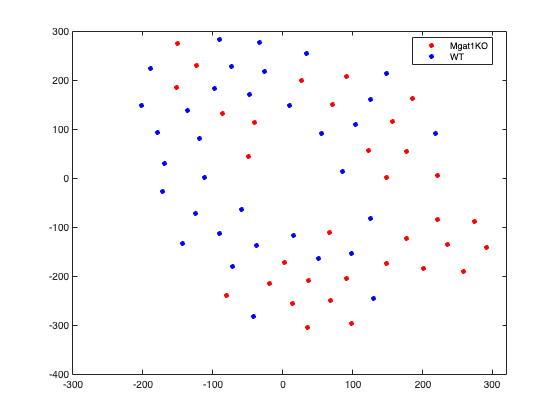

embd = tsne(normalize(table2array(pkss2(:,2:end))),'Algorithm','exact','Distance','spearman');
gscatter(embd(:,1),embd(:,2),g2,'rb')

## Combine the all K+ current models

### PCA

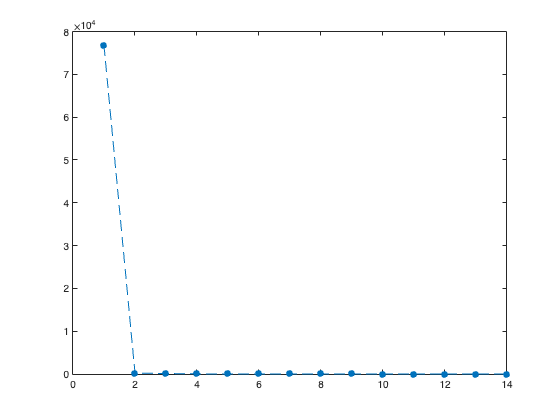

pmx = [table2array(pktof2(:,2:end)), table2array(pkslow12(:,2:end))];

[~,score,latent] = pca(pmx);
plot(latent,'--.','MarkerSize',20)

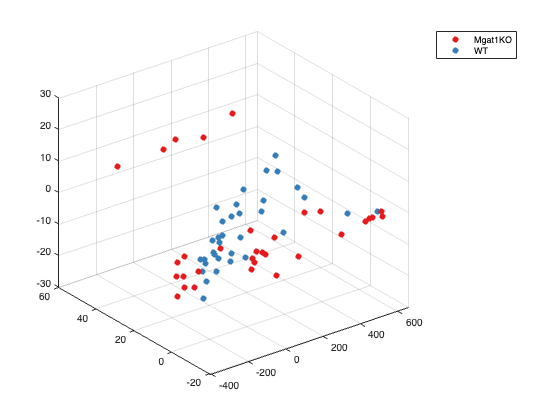

scatter3(score(g==1,1),score(g==1,2),score(g==1,3), 'filled', 'CData',c(g(g==1),:))
hold on
scatter3(score(g==2,1),score(g==2,2),score(g==2,3), 'filled', 'CData',c(g(g==2),:))
hold off
legend(["Mgat1KO","WT"])

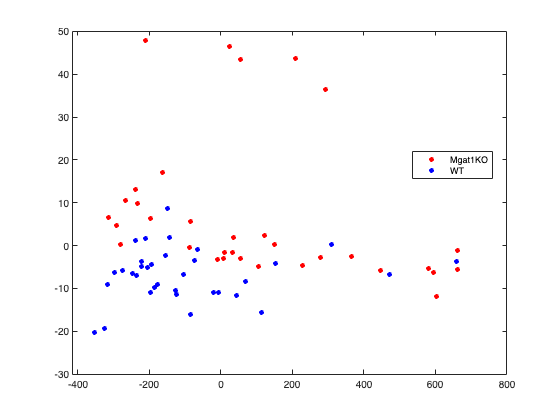

gscatter(score(:,1),score(:,2),g2,'rb');

### t-SNE

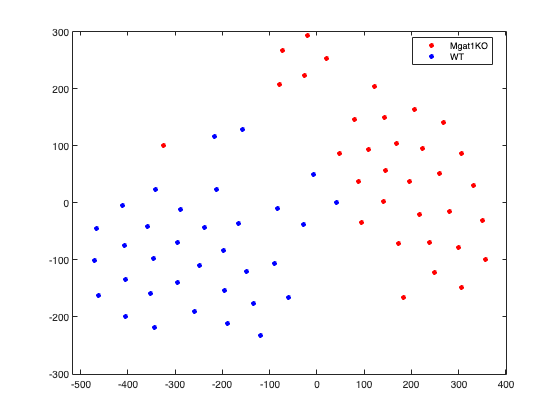

embd = tsne(normalize(pmx),'Algorithm','exact','Distance','spearman');
gscatter(embd(:,1),embd(:,2),g2,'rb')

# Repear the same routine for Experiment 45

## IKtof

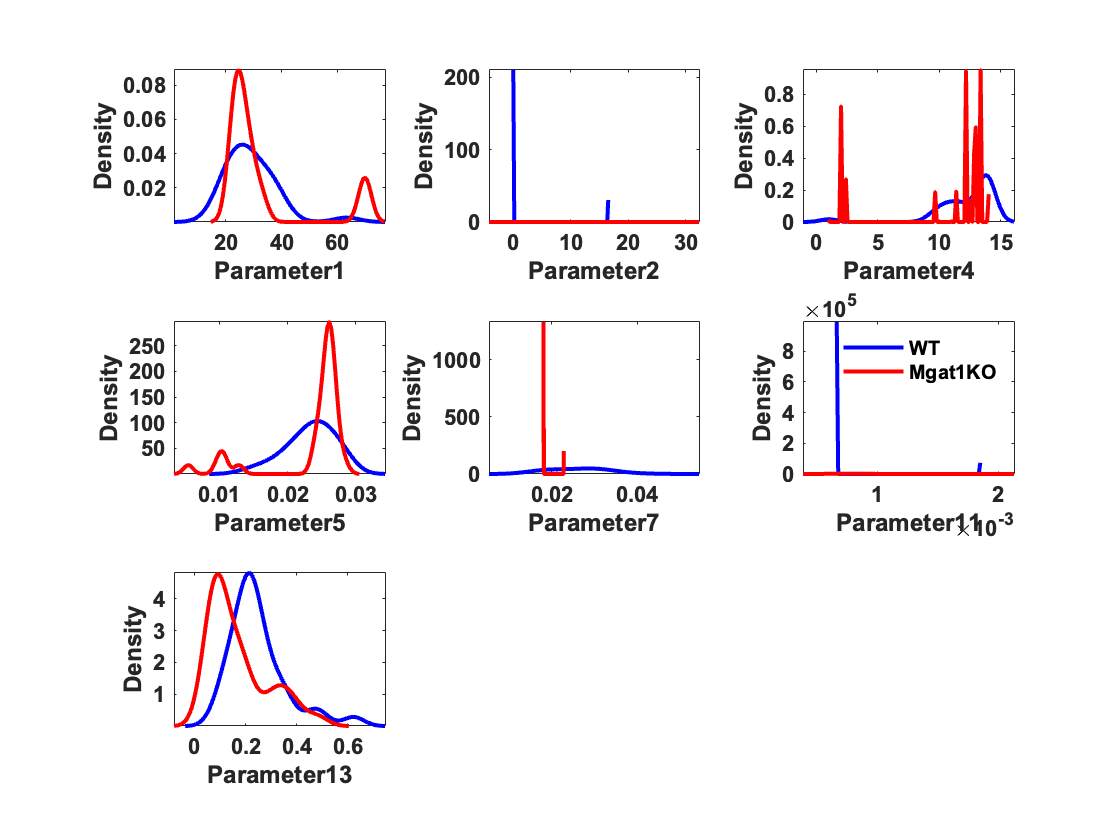

pktof = readtable("exp45_pktof.csv");
pidx = unique(pktof.param);

figure
for i=1:length(pidx)
    psub = pktof(pktof.param==pidx(i),:);
    psub_wt = psub(string(psub.Group)=="WT",:);
    psub_ko = psub(string(psub.Group)=="Mgat1KO",:);

    [f1,xi1] = ksdensity(psub_wt.value);
    [f2,xi2] = ksdensity(psub_ko.value);
    
    subplot(3,3,i)
    plot(xi1,f1, 'Color','blue', 'LineWidth',2)
    hold on
    plot(xi2,f2, 'Color','red', 'LineWidth',2)
    hold off
    axis tight
    xlabel(strcat('Parameter', num2str(pidx(i))))
    ylabel('Density')
    set(gca, 'FontName','Arial', 'FontSize',11, 'FontWeight','bold')

    if i==6
        legend(["WT","Mgat1KO"])
        legend box off
    end
end

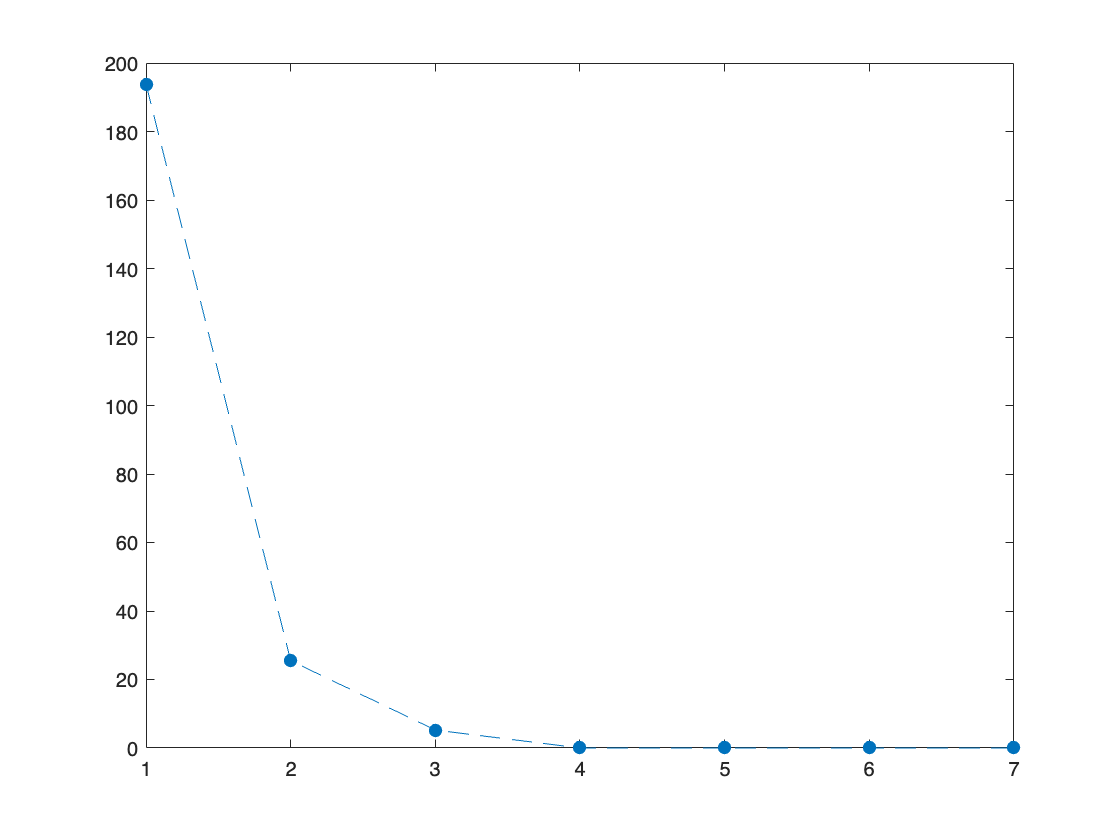

nrow = size(pktof,1)/length(pidx);
pktof2 = array2table(NaN(nrow,length(pidx)+1));
pktof2.Properties.VariableNames(1) = {'Group'};
pktof2.Group = pktof(pktof.param==pidx(1),:).Group;

for i=1:length(pidx)
    pktof2.Properties.VariableNames(i+1) = {strcat('P',num2str(pidx(i)))};
    pktof2(:,i+1)= pktof(pktof.param==pidx(i),'value');
end

[~,score,latent] = pca(table2array(pktof2(:,2:end)));

figure
plot(latent,'--.', 'MarkerSize',20)

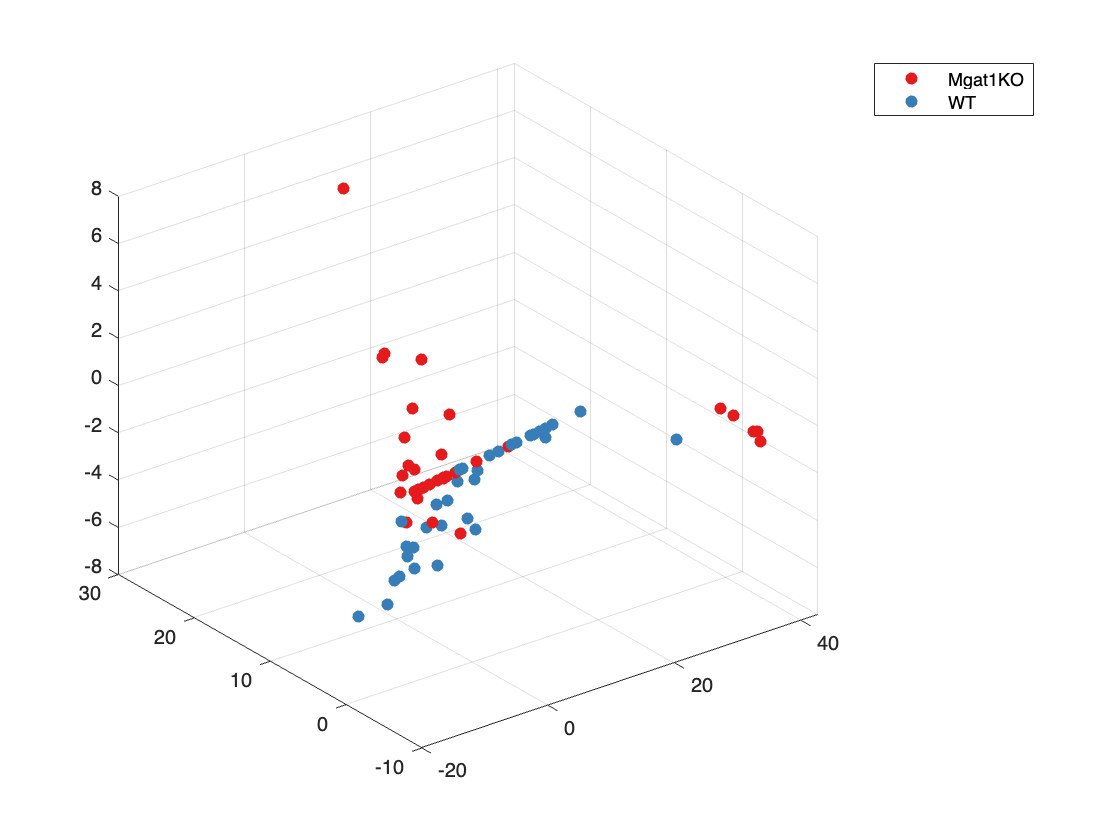

g = NaN(nrow,1);
g(pktof2.Group == "Mgat1KO") = 1;
g(pktof2.Group == "WT") = 2;
c = brewermap(length(unique(g)),'Set1');

scatter3(score(g==1,1),score(g==1,2),score(g==1,3), 'filled', 'CData',c(g(g==1),:))
hold on
scatter3(score(g==2,1),score(g==2,2),score(g==2,3), 'filled', 'CData',c(g(g==2),:))
hold off
legend(["Mgat1KO","WT"])

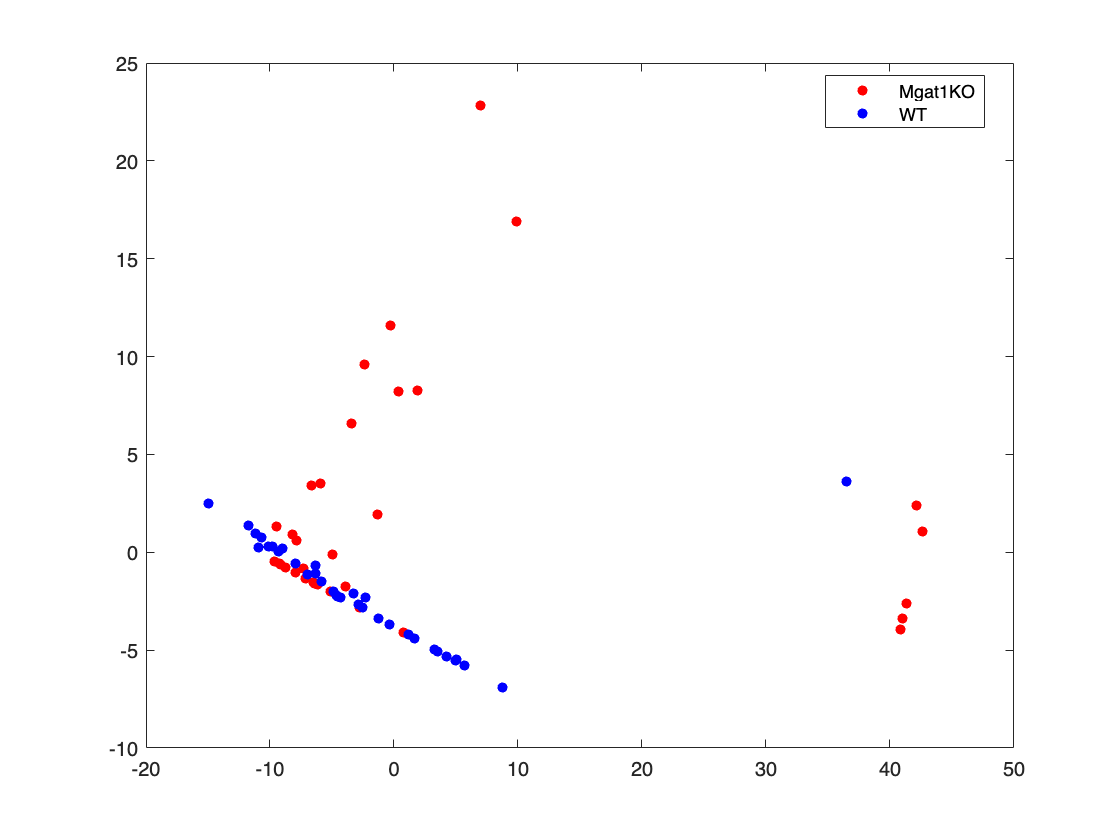

g2 = categorical(pktof2.Group);
gscatter(score(:,1),score(:,2),g2, 'rb');

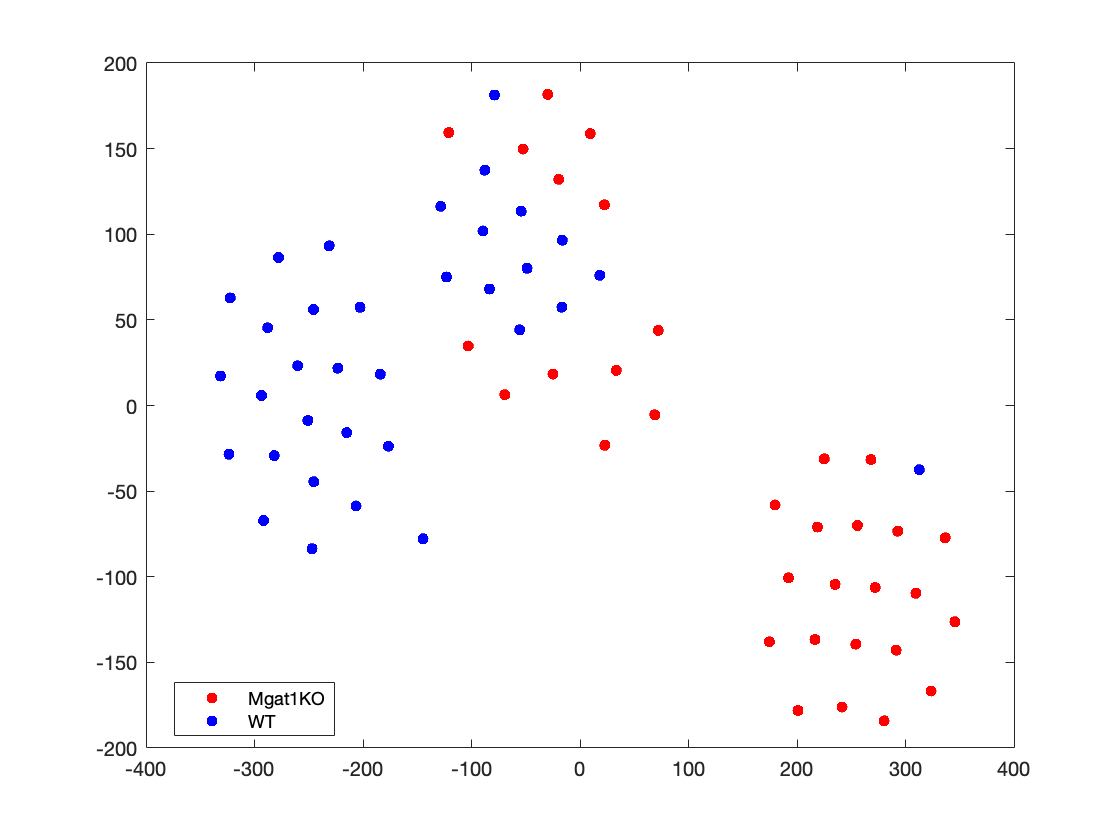


embd = tsne(table2array(pktof2(:,2:end)),'Algorithm','exact','Distance','spearman');
gscatter(embd(:,1),embd(:,2),g2,'rb')